# Kernel bandwidth optimization

Implementation of algorithms in Shimazaki and Shinomoto, 2010

## Fixed bandwidth with MISE optimization

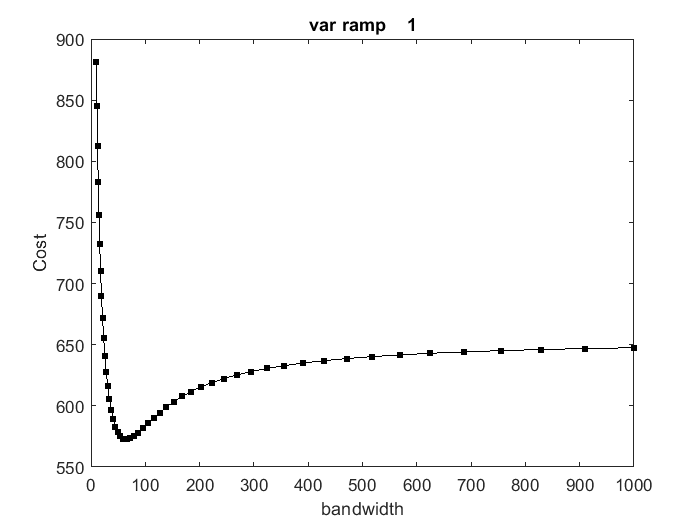

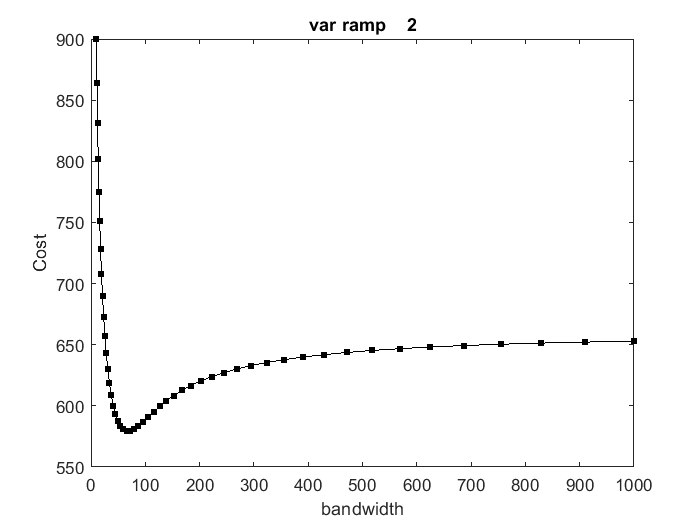

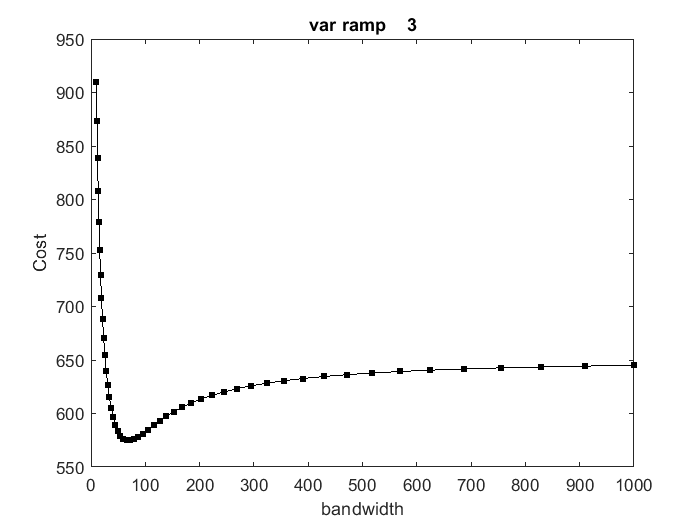

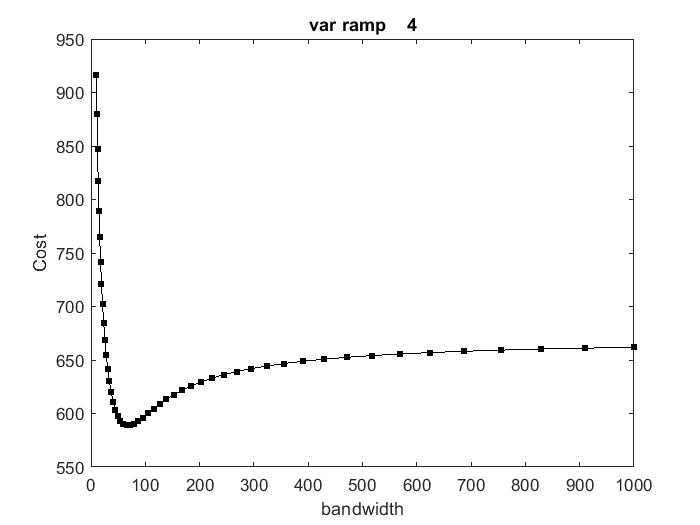

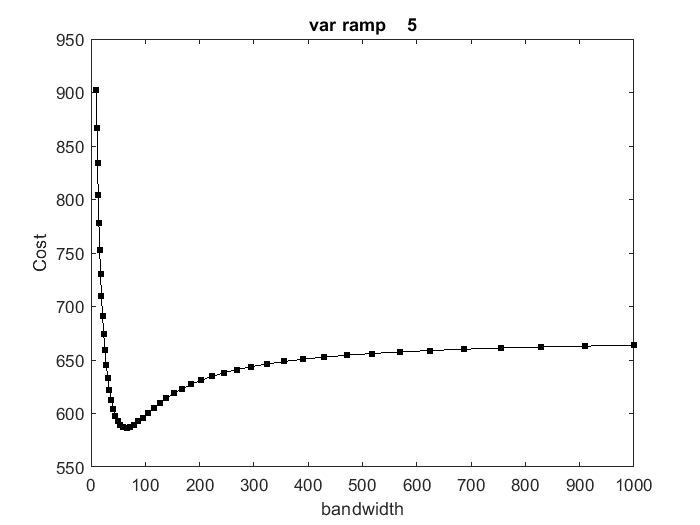

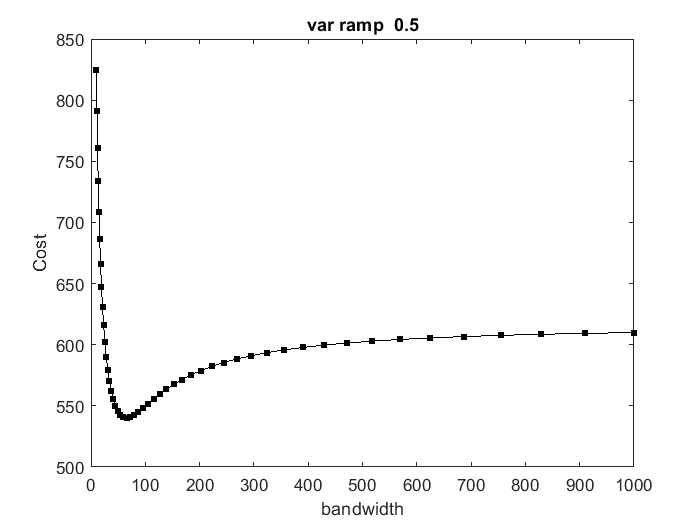

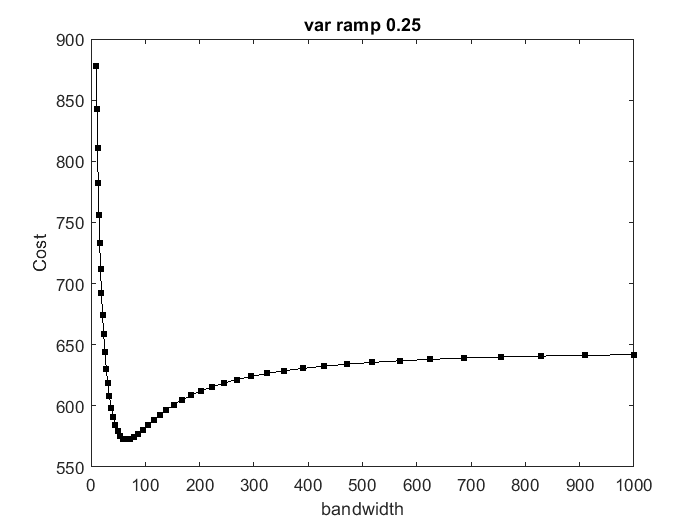

% P is a dataframe that contains all the data for all the protocols.
% Here, the protocols pertain to ramps of variable slopes of 1, 2, 3, 4, 5,
% 0.5, 0.25 seconds - indicated by var ramp 1 on the figure titles.
% raster_data contains the spike timings.

fs = P(1).fs;
start_stim = (P(1).OFF_dur*fs)+1;
stop_stim = (P(1).ON_dur + P(1).OFF_dur)*fs;

for i = 1:length(P)
    
    data_struct = P(i); 
    raster_data = data_struct.raster(:,start_stim:stop_stim);
    n = P(i).complete_trials;
    spike_trian = mean(raster_data,1); % mean of 5 trials
    sptimes = find(spike_trian~=0); % spike timings from the mean spike train 
    N = length(sptimes); % total number of spikes
    cost_func = [];
    bandwidth = logspace(1,3,50);
    
    for bw=1:50
        
        w = bandwidth(bw); 
        sum_factor = 0;
        
        for j = 2:N
            for k= 1:(j-1)
                sum_factor = sum_factor + (exp(-((sptimes(k)-sptimes(j))^2)/(4*w^2)) + 2*sqrt(2)*exp(-((sptimes(k)-sptimes(j))^2)/(2*w^2)));
            end
        end
        
        cost = (N/w) + (2/w)*sum_factor;
        cost_func = [cost_func cost];
    end
    
    figure;
    plot(bandwidth, cost_func, 'k','Marker',".","MarkerSize",10);
    ylabel('Cost');
    xlabel('bandwidth');
    title(replace(data_struct.stim_name, '_', ' '));
    
end